# Ejercicio Nº8

clear;clc;

syms t vc1(t) vc3(t) vc5(t) vc6(t);

## Valores de los componentes 

R1=1;
R2=1;
K1=1;
K2=2;
K3=3;
K4=4;
K5=5;
K6=6;
E=(sin(pi*t*0.2))^2;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[K1*R1 0 K5*R1 0;-R2*K2 0 (K5*R2+R2*K2) -R2*K2; K1 -K3 0 -K6;K2 -K4 -K2 K6+K4+K2];
N=[1 1 0 0;-1 -1 1 0;0 0 0 0;0 0 0 0];
u=[E;0;0;0];


Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

A =    -0.7166   -0.7166    0.3036         0
   -0.2753   -0.2753    0.1336         0
   -0.0567   -0.0567   -0.0607         0
    0.0182    0.0182   -0.0162         0



B=M\u

$$B = \left(\begin{array}{c} \frac{102\,{\sin\left(\frac{\pi \,t}{5}\right)}^{2}}{247}\\ \frac{35\,{\sin\left(\frac{\pi \,t}{5}\right)}^{2}}{247}\\ \frac{29\,{\sin\left(\frac{\pi \,t}{5}\right)}^{2}}{247}\\ -\frac{{\sin\left(\frac{\pi \,t}{5}\right)}^{2}}{494} \end{array}\right)$$

Se definen las variables de estado

x=[vc1;vc3;vc5;vc6]

$$x(t) = \left(\begin{array}{c} {\mathrm{vc}}_{1}\left(t\right)\\ {\mathrm{vc}}_{3}\left(t\right)\\ {\mathrm{vc}}_{5}\left(t\right)\\ {\mathrm{vc}}_{6}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) ==  A*x + B

$$odes(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{vc}}_{1}\left(t\right)=\frac{102\,\sigma_{1}}{247}-\frac{177\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{177\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{75\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{3}\left(t\right)=\frac{35\,\sigma_{1}}{247}-\frac{68\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{68\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{33\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{5}\left(t\right)=\frac{29\,\sigma_{1}}{247}-\frac{14\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{14\,{\mathrm{vc}}_{3}\left(t\right)}{247}-\frac{15\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{6}\left(t\right)=-\frac{\sigma_{1}}{494}+\frac{9\,{\mathrm{vc}}_{1}\left(t\right)}{494}+\frac{9\,{\mathrm{vc}}_{3}\left(t\right)}{494}-\frac{4\,{\mathrm{vc}}_{5}\left(t\right)}{247} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\frac{\pi \,t}{5}\right)}^{2} \end{array}$$

Resolviendo el sistema con el comando dsolve

[vc1Sol(t), vc3Sol(t),vc5(t),vc6(t)] = dsolve(odes)

$$vc1Sol(t) = \begin{array}{l} {\mathrm{e}}^{\frac{t\,\left(\sqrt{11713}-130\right)}{247}}\,\left(\sigma_{5}-\frac{243}{14}\right)\,\left(C_{3}-\left(\frac{67\,\sqrt{11713}}{890188}-\frac{1}{988}\right)\,\left(\frac{\sigma_{7}}{2\,\sigma_{2}}-\frac{\sigma_{7}\,\left(\cos\left(\sigma_{3}\right)\,\sigma_{2}-\frac{2\,\pi \,\sin\left(\sigma_{3}\right)}{5}\right)}{2\,\left({\sigma_{2}}^{2}+\frac{4\,\pi^{2}}{25}\right)}\right)\right)-{\mathrm{e}}^{-\frac{t\,\left(\sqrt{11713}+130\right)}{247}}\,\left(\sigma_{5}+\frac{243}{14}\right)\,\left(C_{4}-\sigma_{6}\,\left(\frac{137\,\sqrt{11713}}{655928}-\frac{1}{56}\right)+\frac{95\,\sigma_{6}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}\,\left(55025\,\pi +500\,\pi \,\sqrt{11713}+18772\,\pi^{3}\right)}{3604\,\sigma_{1}}+\frac{25\,\sigma_{6}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}\,\left(\sqrt{11713}+130\right)\,\left(500\,\sqrt{11713}+18772\,\pi^{2}+55025\right)}{93704\,\sigma_{1}}\right)-C_{2}\\ \mathrm{where}\\ \sigma_{1}=55025000\,\sqrt{11713}+18772000\,\sqrt{11713}\,\pi^{2}+2065858600\,\pi^{2}+352387984\,\pi^{4}+5956000625\\ \sigma_{2}=\frac{\sqrt{11713}}{247}-\frac{10}{19}\\ \sigma_{3}=\frac{2\,\pi \,t}{5}\\ \sigma_{4}=67\,\sqrt{11713}+901\\ \sigma_{5}=\frac{3\,\sqrt{11713}}{14}\\ \sigma_{6}={\mathrm{e}}^{\frac{10\,t}{19}+\sigma_{8}}\\ \sigma_{7}={\mathrm{e}}^{\frac{10\,t}{19}-\sigma_{8}}\\ \sigma_{8}=\frac{\sqrt{11713}\,t}{247} \end{array}$$

$$vc3Sol(t) = \begin{array}{l} C_{2}-{\mathrm{e}}^{-\frac{t\,\left(\sqrt{11713}+130\right)}{247}}\,\left(\frac{\sqrt{11713}}{14}+\frac{109}{14}\right)\,\left(C_{4}-\sigma_{5}\,\left(\frac{137\,\sqrt{11713}}{655928}-\frac{1}{56}\right)+\frac{95\,\sigma_{5}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}\,\left(55025\,\pi +500\,\pi \,\sqrt{11713}+18772\,\pi^{3}\right)}{3604\,\sigma_{1}}+\frac{25\,\sigma_{5}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}\,\left(\sqrt{11713}+130\right)\,\left(500\,\sqrt{11713}+18772\,\pi^{2}+55025\right)}{93704\,\sigma_{1}}\right)+{\mathrm{e}}^{\frac{t\,\left(\sqrt{11713}-130\right)}{247}}\,\left(\frac{\sqrt{11713}}{14}-\frac{109}{14}\right)\,\left(C_{3}-\left(\frac{67\,\sqrt{11713}}{890188}-\frac{1}{988}\right)\,\left(\frac{\sigma_{6}}{2\,\sigma_{2}}-\frac{\sigma_{6}\,\left(\cos\left(\sigma_{3}\right)\,\sigma_{2}-\frac{2\,\pi \,\sin\left(\sigma_{3}\right)}{5}\right)}{2\,\left({\sigma_{2}}^{2}+\frac{4\,\pi^{2}}{25}\right)}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=55025000\,\sqrt{11713}+18772000\,\sqrt{11713}\,\pi^{2}+2065858600\,\pi^{2}+352387984\,\pi^{4}+5956000625\\ \sigma_{2}=\frac{\sqrt{11713}}{247}-\frac{10}{19}\\ \sigma_{3}=\frac{2\,\pi \,t}{5}\\ \sigma_{4}=67\,\sqrt{11713}+901\\ \sigma_{5}={\mathrm{e}}^{\frac{10\,t}{19}+\sigma_{7}}\\ \sigma_{6}={\mathrm{e}}^{\frac{10\,t}{19}-\sigma_{7}}\\ \sigma_{7}=\frac{\sqrt{11713}\,t}{247} \end{array}$$

$$vc5(t) = \begin{array}{l} {\mathrm{e}}^{\frac{t\,\left(\sqrt{11713}-130\right)}{247}}\,\left(\frac{\sqrt{11713}}{14}+\frac{59}{14}\right)\,\left(C_{3}-\left(\frac{67\,\sqrt{11713}}{890188}-\frac{1}{988}\right)\,\left(\frac{\sigma_{6}}{2\,\sigma_{2}}-\frac{\sigma_{6}\,\left(\cos\left(\sigma_{3}\right)\,\sigma_{2}-\frac{2\,\pi \,\sin\left(\sigma_{3}\right)}{5}\right)}{2\,\left({\sigma_{2}}^{2}+\frac{4\,\pi^{2}}{25}\right)}\right)\right)-{\mathrm{e}}^{-\frac{t\,\left(\sqrt{11713}+130\right)}{247}}\,\left(\frac{\sqrt{11713}}{14}-\frac{59}{14}\right)\,\left(C_{4}-\sigma_{5}\,\left(\frac{137\,\sqrt{11713}}{655928}-\frac{1}{56}\right)+\frac{95\,\sigma_{5}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}\,\left(55025\,\pi +500\,\pi \,\sqrt{11713}+18772\,\pi^{3}\right)}{3604\,\sigma_{1}}+\frac{25\,\sigma_{5}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}\,\left(\sqrt{11713}+130\right)\,\left(500\,\sqrt{11713}+18772\,\pi^{2}+55025\right)}{93704\,\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=55025000\,\sqrt{11713}+18772000\,\sqrt{11713}\,\pi^{2}+2065858600\,\pi^{2}+352387984\,\pi^{4}+5956000625\\ \sigma_{2}=\frac{\sqrt{11713}}{247}-\frac{10}{19}\\ \sigma_{3}=\frac{2\,\pi \,t}{5}\\ \sigma_{4}=67\,\sqrt{11713}+901\\ \sigma_{5}={\mathrm{e}}^{\frac{10\,t}{19}+\sigma_{7}}\\ \sigma_{6}={\mathrm{e}}^{\frac{10\,t}{19}-\sigma_{7}}\\ \sigma_{7}=\frac{\sqrt{11713}\,t}{247} \end{array}$$

$$vc6(t) = \begin{array}{l} C_{1}+{\mathrm{e}}^{-\frac{t\,\left(\sqrt{11713}+130\right)}{247}}\,\left(C_{4}-\sigma_{5}\,\left(\frac{137\,\sqrt{11713}}{655928}-\frac{1}{56}\right)+\frac{95\,\sigma_{5}\,\sin\left(\sigma_{3}\right)\,\sigma_{4}\,\left(55025\,\pi +500\,\pi \,\sqrt{11713}+18772\,\pi^{3}\right)}{3604\,\sigma_{1}}+\frac{25\,\sigma_{5}\,\cos\left(\sigma_{3}\right)\,\sigma_{4}\,\left(\sqrt{11713}+130\right)\,\left(500\,\sqrt{11713}+18772\,\pi^{2}+55025\right)}{93704\,\sigma_{1}}\right)+{\mathrm{e}}^{\frac{t\,\left(\sqrt{11713}-130\right)}{247}}\,\left(C_{3}-\left(\frac{67\,\sqrt{11713}}{890188}-\frac{1}{988}\right)\,\left(\frac{\sigma_{6}}{2\,\sigma_{2}}-\frac{\sigma_{6}\,\left(\cos\left(\sigma_{3}\right)\,\sigma_{2}-\frac{2\,\pi \,\sin\left(\sigma_{3}\right)}{5}\right)}{2\,\left({\sigma_{2}}^{2}+\frac{4\,\pi^{2}}{25}\right)}\right)\right)\\ \mathrm{where}\\ \sigma_{1}=55025000\,\sqrt{11713}+18772000\,\sqrt{11713}\,\pi^{2}+2065858600\,\pi^{2}+352387984\,\pi^{4}+5956000625\\ \sigma_{2}=\frac{\sqrt{11713}}{247}-\frac{10}{19}\\ \sigma_{3}=\frac{2\,\pi \,t}{5}\\ \sigma_{4}=67\,\sqrt{11713}+901\\ \sigma_{5}={\mathrm{e}}^{\frac{10\,t}{19}+\sigma_{7}}\\ \sigma_{6}={\mathrm{e}}^{\frac{10\,t}{19}-\sigma_{7}}\\ \sigma_{7}=\frac{\sqrt{11713}\,t}{247} \end{array}$$

syms C1 C2 C3 C4
v01=0;
v02=0;
v03=0;
v04=0;
v05=0;
v06=0;
Xant=[v01;v03;v05;v06];
constantes=x(0)==Xant;
odes = diff(x) == A*x + B

$$odes(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{vc}}_{1}\left(t\right)=\frac{102\,\sigma_{1}}{247}-\frac{177\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{177\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{75\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{3}\left(t\right)=\frac{35\,\sigma_{1}}{247}-\frac{68\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{68\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{33\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{5}\left(t\right)=\frac{29\,\sigma_{1}}{247}-\frac{14\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{14\,{\mathrm{vc}}_{3}\left(t\right)}{247}-\frac{15\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{6}\left(t\right)=-\frac{\sigma_{1}}{494}+\frac{9\,{\mathrm{vc}}_{1}\left(t\right)}{494}+\frac{9\,{\mathrm{vc}}_{3}\left(t\right)}{494}-\frac{4\,{\mathrm{vc}}_{5}\left(t\right)}{247} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sin\left(\frac{\pi \,t}{5}\right)}^{2} \end{array}$$

[vc1Sol(t), vc3Sol(t),vc5Sol(t),vc6Sol(t)] = dsolve(odes,constantes)

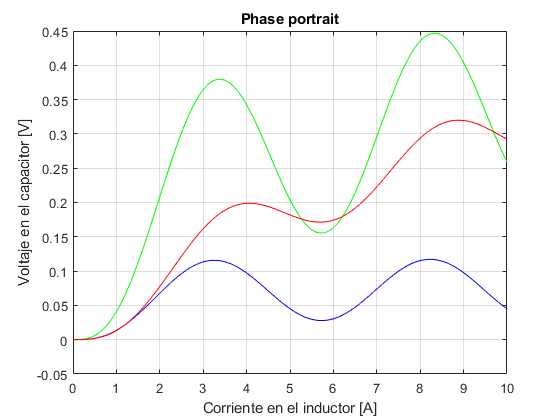

clear t
ti=0;
tf=10;
h=0.1;
t=ti:h:tf;
plot(t,vc1Sol(t),'-g',t,vc3Sol(t),'-b',t,vc5Sol(t),'-r');
title('Phase portrait')
xlabel('Corriente en el inductor [A]')
ylabel('Voltaje en el capacitor [V]')
grid on